P1.

x = 1 : 10;
y = sin(1 : 10);

phi = @(x)[ones(1, length(x)); x; x.^2; x.^3; x.^4; x.^5];

x_approx = x(1) : (x(length(x)) - x(1)) / 100 : x(length(x));
y_approx = least_squares_approx(x, y, phi, x_approx);

fprintf("Problema 1");

Problema 1

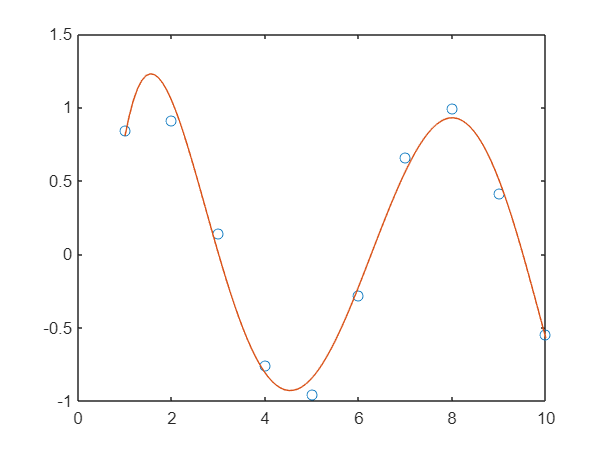

plot(x, y, 'o', x_approx, y_approx, '-');

P2.

x = [-1.024940 -0.949898 -0.866114 -0.773392 -0.671372 -0.559524 -0.437067 -0.302909 -0.159493 -0.007464];
y = [-0.389269 -0.322894 -0.265256 -0.216557 -0.177152 -0.147582 -0.128618 -0.121353 -0.127348 -0.148895];

% Model parabolic
phi = @(x)[ones(1, length(x)); x.^2];

x_approx = x(1):(x(length(x)) - x(1)) / 100 : x(length(x));
y_approx = least_squares_approx(x, y, phi, x_approx);

fprintf("Problema 2");

Problema 2

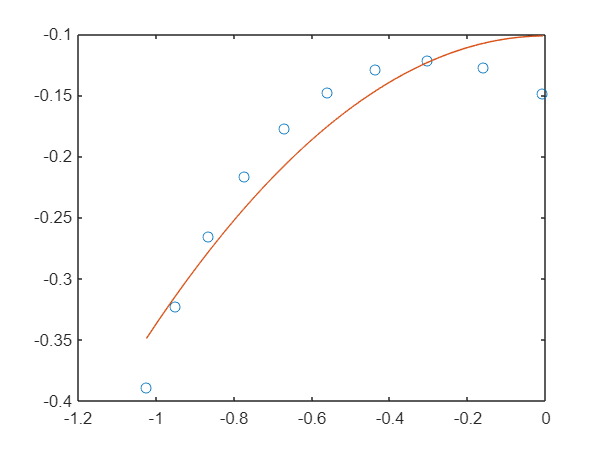

plot(x, y, 'o', x_approx, y_approx, '-');

P3.

% A - B - C - D
% AB = x1; BC = x2; CD = x3;
% X = [ AD; AC; BD; AB; CD] 
X = [1 1 1; 1 1 0; 0 1 1; 1 0 0; 0 0 1];
Y = [89; 67; 53; 35; 20];

fprintf("Problema 3");

Problema 3

a = linsolve(X, Y)

a =    35.1250
   32.5000
   20.6250


P4.

% Potrivire polinomială:
y = [75995 91972 105710 123200 131670 150700 179320 203210 226510 249630 281420 308790]';
t = (1900:10:2010)';
x = (1890:1:2019)';
w = 1975;

fprintf("Problema 4");

Problema 4

fprintf("Potrivire polinomială:");

Potrivire polinomială:

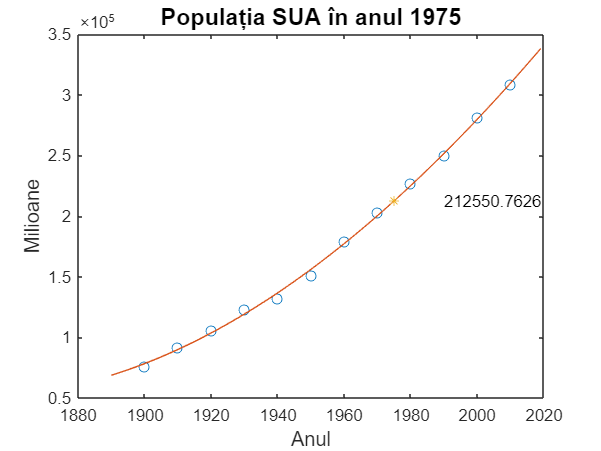


s = (t - 1950) / 50;
xs = (x - 1950) / 50;
cs = polyfit(s, y, 3);
zs = polyval(cs, xs);
est = polyval(cs, (1975 - 1950) / 50);
plot(t, y, 'o', x, zs, '-', w, est, '*');
text(1990, est, num2str(est));
title("Populația SUA în anul 1975", "FontSize", 14);
xlabel("Anul", "FontSize", 12);
ylabel("Milioane", "FontSize", 12);

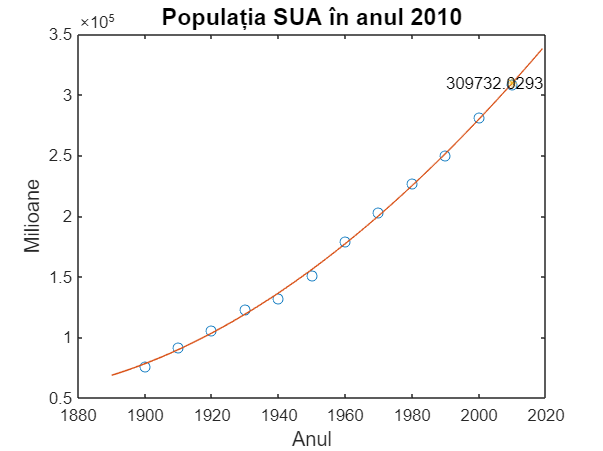


w = 2010;

s = (t - 1950) / 50;
xs = (x - 1950) / 50;
cs = polyfit(s, y, 3);
zs = polyval(cs, xs);
est = polyval(cs, (2010 - 1950) / 50);
plot(t, y, 'o', x, zs, '-', w, est, '*');
text(1990, est, num2str(est));
title("Populația SUA în anul 2010", "FontSize", 14);
xlabel("Anul", "FontSize", 12);
ylabel("Milioane", "FontSize", 12);